
%180079X
A = 0;
B = 7;
C = 9;
%parameters
Ap = 0.03 + (0.01*A)    %dB

Ap = 0.0300

Aa = 45 + B             %dB

Aa = 52

Wp1 = (C*100) + 300     %rad/s

Wp1 = 1200

Wp2 = (C*100) + 700     %rad/s

Wp2 = 1600

Wa1 = (C*100) + 150     %rad/s

Wa1 = 1050

Wa2 = (C*100) + 800     %rad/s

Wa2 = 1700

Ws = 2*((C*100) + 1200)    %rad/s

Ws = 4200

Bt = min(Wp1-Wa1, Wa2-Wp2);
Wc1 = Wp1 - (Bt/2);
Wc2 = Wp2 + (Bt/2);
T = 2*pi/Ws;
len = 150;
n = -len:len;

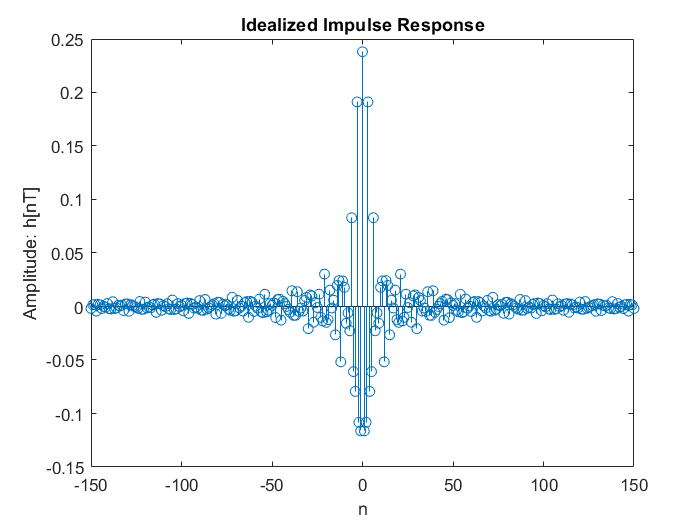

%1
%ideal impulse response
hnT = ImpulseR(n,T,Ws,Wc1,Wc2);
stem(n,hnT);
xlabel("n")
ylabel("Amplitude: h[nT]")
title("Idealized Impulse Response")

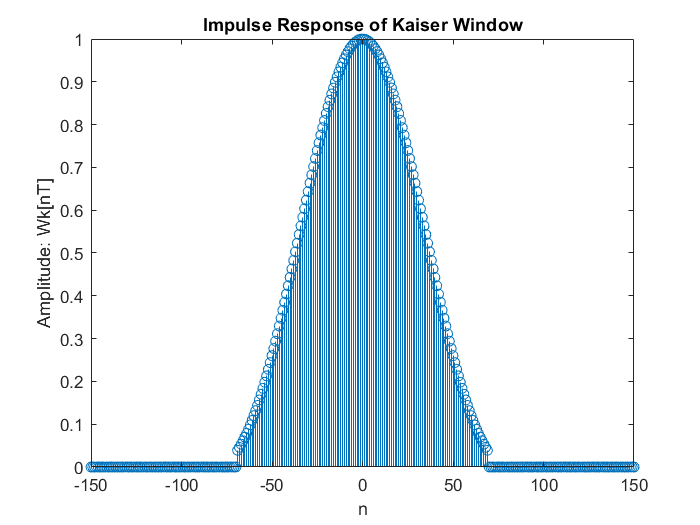


%calculating delta
delta_p = (10^(0.05*Ap)-1)/(10^(0.05*Ap)+1);
delta_a = 10^(-0.05*Aa);
delta = min(delta_p,delta_a);
%calculating actual Aa
Aa_act = -20*log10(delta);
%calculating alpha
alpha = getAlpha(Aa_act);
%calculating D
D = getD(Aa_act);
%getting N
N = getN(Ws,D,Bt);
%kaiser window
WknT = getWknT(alpha,n,N);
stem(n,WknT);
xlabel("n")
ylabel("Amplitude: Wk[nT]")
title("Impulse Response of Kaiser Window")

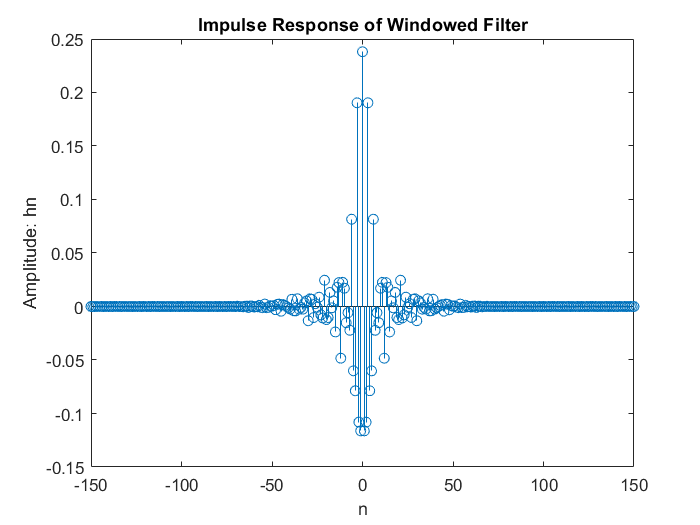


%filter function in time domain
hn=hnT.*WknT;
stem(n,hn) 
xlabel("n")
ylabel("Amplitude: hn")
title("Impulse Response of Windowed Filter")

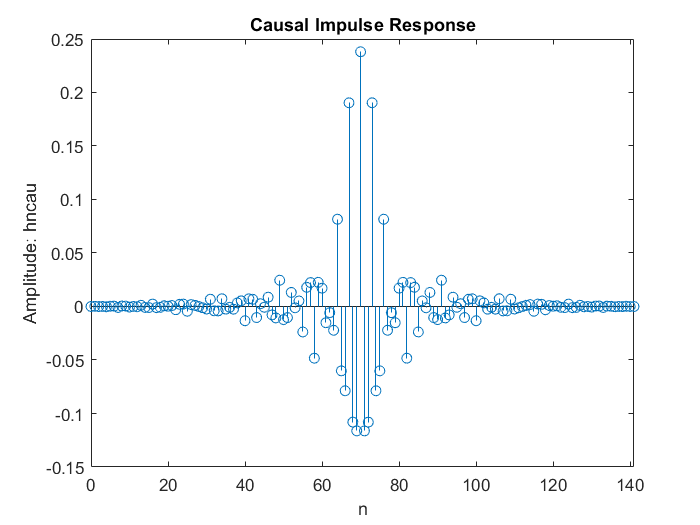

%2
%causal impulse response
hncau = zeros(size(hn));
for cnt = 1:(length(hn)-(N-1)/2)
    hncau(cnt + (N-1)/2) = hn(cnt);
end
stem(n,hncau);
xlim([0 N]) 
xlabel("n")
ylabel("Amplitude: hncau")
title("Causal Impulse Response")

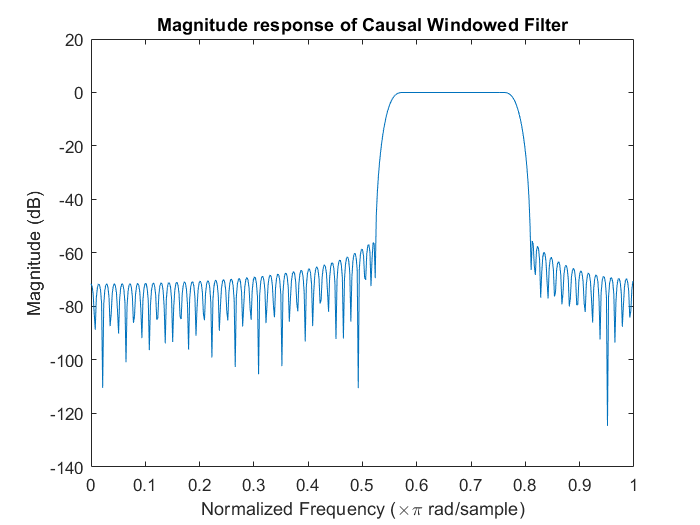

%3
%magnitude response of the filter
[h,w]=freqz(hncau,1); 
plot(w/pi,db(h))
xlabel("Normalized Frequency (\times\pi rad/sample)")
ylabel("Magnitude (dB)")
title("Magnitude response of Causal Windowed Filter")

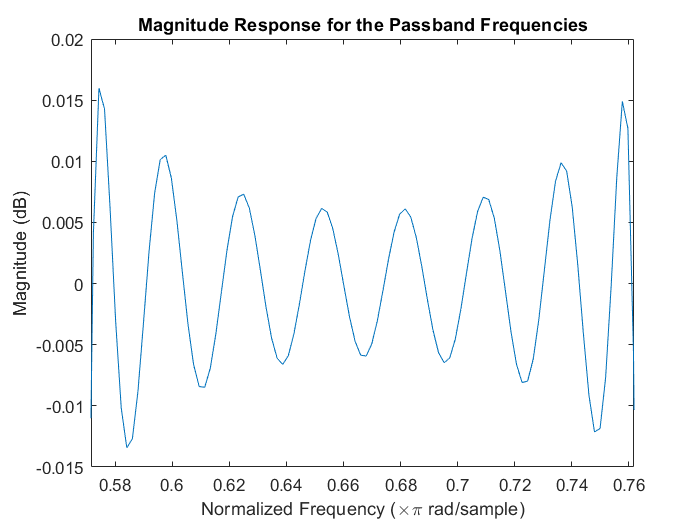

%4
%magnitude response of pass band
plot(w/pi,db(h))
xlim([Wp1*2/Ws Wp2*2/Ws])
xlabel("Normalized Frequency (\times\pi rad/sample)")
ylabel("Magnitude (dB)")
title("Magnitude Response for the Passband Frequencies")

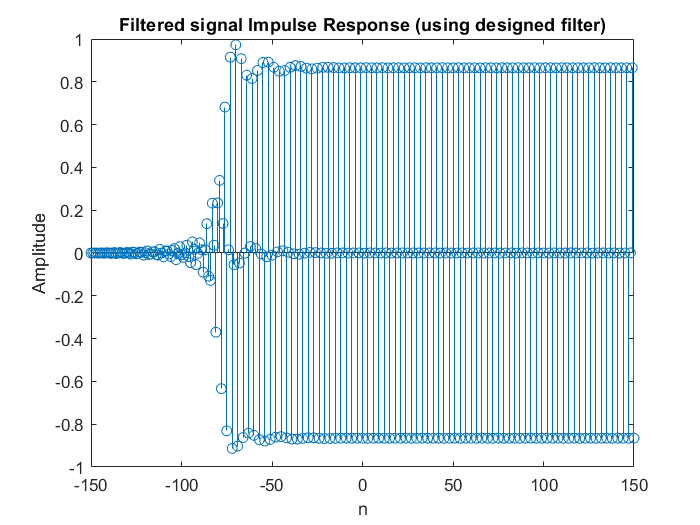

%5
%checking the excitation
xnT = sin((Wa1/2)*n*T)+sin(((Wp1+Wp2)/2)*n*T)+sin(((Wa2+Ws/2)/2)*n*T);
%applying the filter 
Filt = conv(hncau,xnT,"same"); 
stem(n,Filt);
xlabel("n")
ylabel("Amplitude")
title("Filtered signal Impulse Response (using designed filter)")

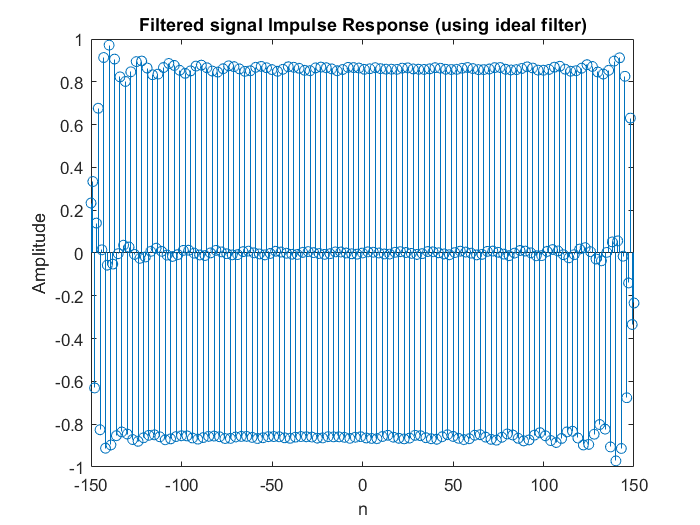


IdFilt = conv(ImpulseR(n,T,Ws,Wc1,Wc2),xnT,"same"); %applying the ideal filter to the signal
stem(n,IdFilt)
xlabel("n")
ylabel("Amplitude")
title("Filtered signal Impulse Response (using ideal filter)")

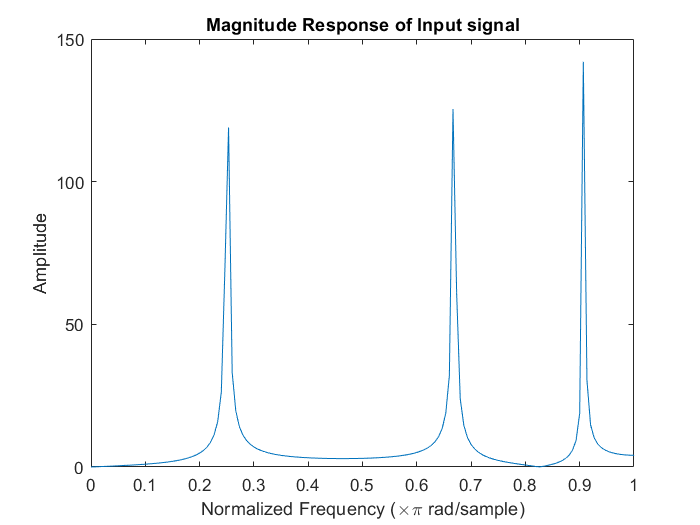

%6
%frequency domain 
freq=(0:2*len)/len; 
%DTFT of input signal
infft=fft(xnT); 
plot(freq,abs(infft)) 
xlim([0 1])
xlabel("Normalized Frequency (\times\pi rad/sample)")
ylabel("Amplitude")
title("Magnitude Response of Input signal")

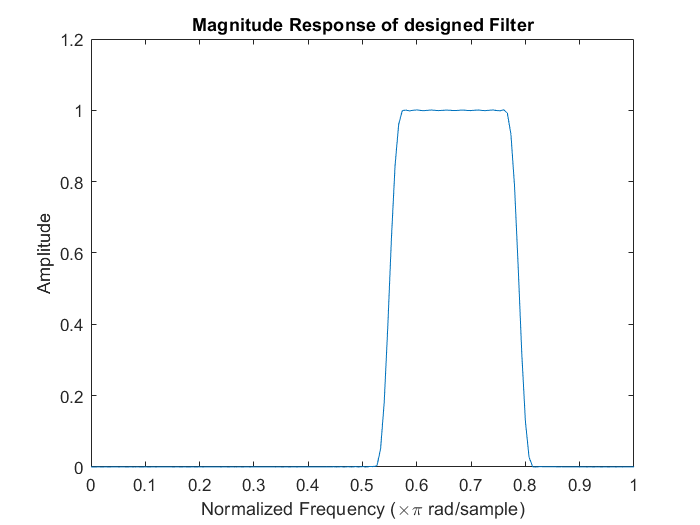


%DTFT of designed filter
filtfft=fft(hncau); 
plot(freq,abs(filtfft)) 
xlim([0 1])
xlabel("Normalized Frequency (\times\pi rad/sample)")
ylabel("Amplitude")
title("Magnitude Response of designed Filter")

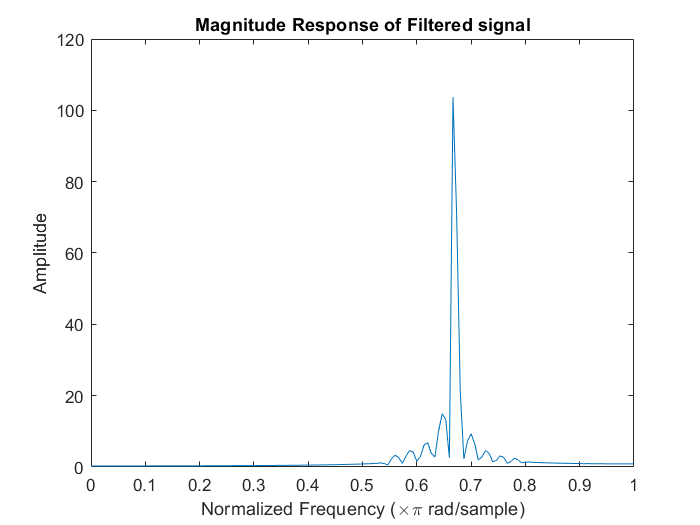


%DTFT of filtered signal
outfft=fft(Filt); 
plot(freq,abs(outfft))
xlim([0 1])
xlabel("Normalized Frequency (\times\pi rad/sample)")
ylabel("Amplitude")
title("Magnitude Response of Filtered signal")

FUNCTIONS

function [hnT] = ImpulseR(n,T,Ws,Wc1,Wc2)
hnT = zeros(size(n));
for num = n
    if num == 0
        hnT(n==num) = 2*(Wc2-Wc1)/Ws;
    else
        hnT(n==num) = (sin(Wc2*num*T)-sin(Wc1*num*T))/(num*pi);
    end
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [alpha] = getAlpha(Aa_act)
if Aa_act<=21
    alpha = 0;
else
    if Aa_act<=50
        alpha = (0.5842*(Aa_act-21)^0.4)+(0.07886*(Aa_act-21));
    else
        alpha = 0.1102*(Aa_act-8.7);
    end
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [D] = getD(Aa_act)
if Aa_act<=21
    D = 0.9222;
else
    D = (Aa_act-7.95)/14.36;
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [N] = getN(Ws,D,Bt)
Ntemp = ((Ws*D)/Bt)+1;
Nint = round(Ntemp);
if Nint<Ntemp
    Nint = Nint+1;
end
if mod(Nint,2)==1
    N = Nint;
else 
    N = Nint+1;
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [W] = getWknT(alpha,n,N)
beta = alpha*(1-(2*n/(N-1)).^2).^0.5;
W = Io(beta)/Io(alpha);
%W = zeros(size(n));
for num1 = n
    %beta = alpha*(1-(2*num1/(N-1)).^2).^0.5;
    if abs(num1) >= ((N-1)/2)
        W(n==num1) = 0;
    %else
        %W(n==num1) = 0;
    end
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [I] = Io(n)
I = zeros(size(n));
for k = 1:10
    I = I + (((n/2).^k)*(1/factorial(k))).^2;
end
I = 1 + I;
end